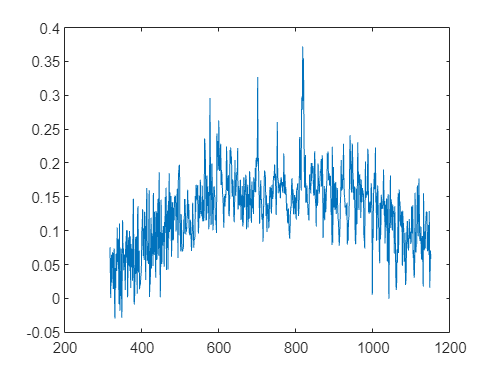

clear all;

load('\\Artemis-pc\e\Data\2023-10-18\Abs-207\OD_FR_2.mat');
startpoint=[143 89];
endpoint=[1151 100];
xlist=startpoint(1):endpoint(1);
ref=round((startpoint(2)-endpoint(2))/(startpoint(1)-endpoint(1)).*(xlist-startpoint(1))+startpoint(2));
for i=1:length(ref)
    ODdata(i)=OD_FR(ref(i),xlist(i));
end
plot(xlist,ODdata)